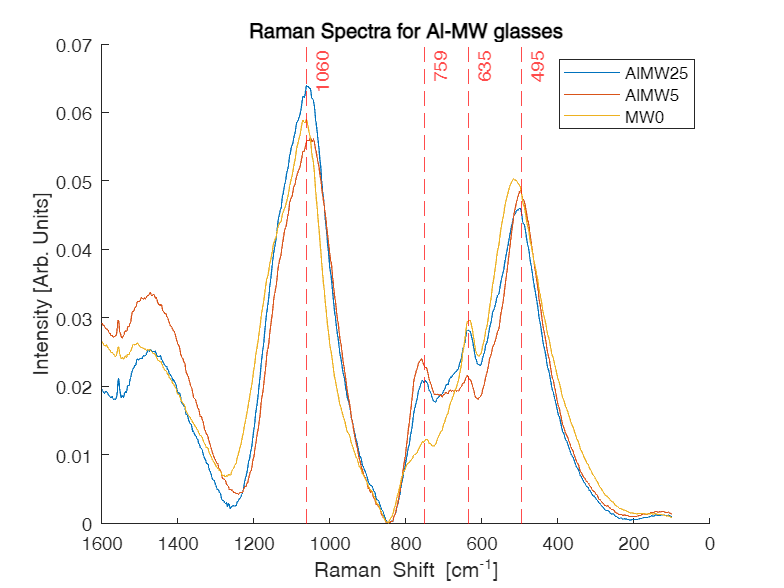

%A script that opens all csvs in a a specified directory and does a bunch
%of raman plots.

%NOTE: For now 050524 all files need to be of same length and the raman
%shift of the first file is taken as the x axis values.

%clearing crap
clear all
clf

%selecting fodler to loop through
folder = "C:\Users\Jack\MATLAB Drive\PhD Work\Raman Plotter_050524\Plot Data\Padova\";
%setting graph title
%tit = "Raman Shfit for 1, 2, 3, 4mol% Fe2O3";
tit = "Raman Spectra for Al-MW glasses";

%extracting full list of files
files = dir(fullfile(folder, "*.csv"));

%looping through and importing all folders
for i = 1:length(files)

    %full file path
    path = fullfile(folder, files(i).name);

    import = readtable(path);
    
    %plotting data
    plot(import{:,1},import{:,2})
    hold on %plotting on same graph

    %checking if we are on the first to set up storage and store x axis
    if i == 1

        data = import;
    
    else % data should always exist after this else

        %concatenating columns
        data = [data, import(:,2)]; 


    end
     
end

%extra vertical lines
xline([1060 750 635 495], "--", ["1060" "759" "635" "495"], "color","red");

%labelling gprah
xlabel("Raman Shift [cm^{-1}]")
%xlabel("Raman Shift [cm^{-1}]",'Position', [0, -0.01, 0]) %moves X axis label if needed
ylabel("Intensity [Arb. Units]")
title(tit)
legend(data.Properties.VariableNames{2:end}); % Omitting the first column header

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
% ax.YAxisLocation = "origin";
set(gca, 'xdir','reverse');
box off;

hold off %ending plotting